# Testing del metodo di Jacobi

### Casi d'uso

Si testa il software su matrici sparse di notevoli dimensioni, generate usando funzioni Matlab non singolari e ben condizionate. Si illustra, attraverso grafico, la struttura delle matrici di test. Un primo esempio di matrice ben condizionata:

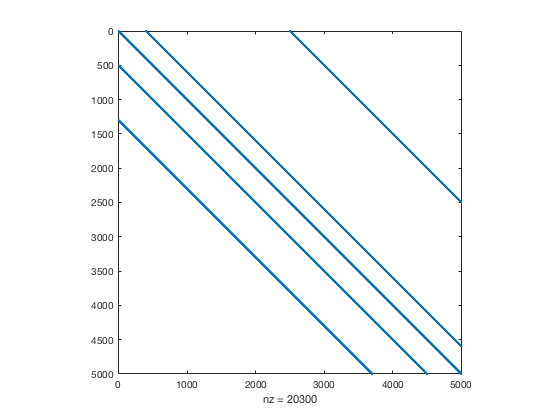

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c =      2.269252419481775e+00


[sol, niter] = Jacobi(Z, b)

sol =      1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00


niter =     11


Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza:

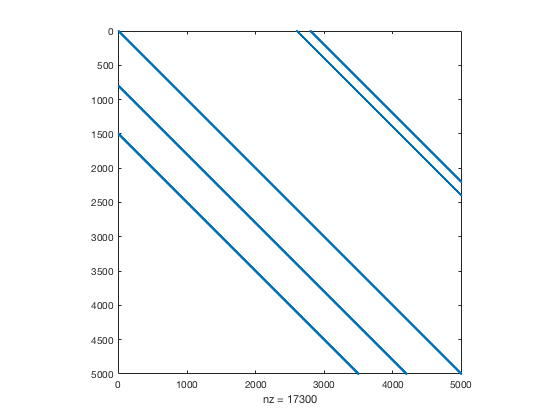

n = 5000;
e = ones(n,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2600 2800], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c =      6.369630366796545e+00


[sol, niter] = Jacobi(Z, b, 10^-9)

sol =      1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00
     1.000000000024874e+00


niter =     42


Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza e il numero massimo di iterazioni:

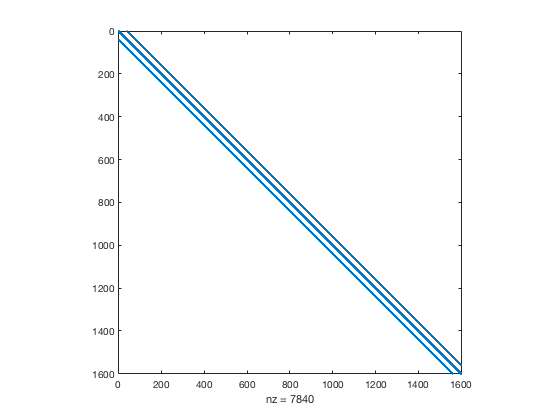

X = gallery('poisson',40);
spy(X)

c = condest(X)

c =      9.892689755980469e+02


x = ones(1600,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,3000)

sol =      9.999980078246928e-01
     9.999960273402626e-01
     9.999940701689792e-01
     9.999921477963023e-01
     9.999902715034789e-01
     9.999884523013416e-01
     9.999867008656915e-01
     9.999850274746498e-01
     9.999834419483404e-01
     9.999819535912623e-01


niter =         2881


### Casi di errore

Utilizziamo la matrice sparsa di Toeppen che presenta elementi nulli sulla diagonale. Per questo tipo di matrici, il metodo di Jacobi non è definito.

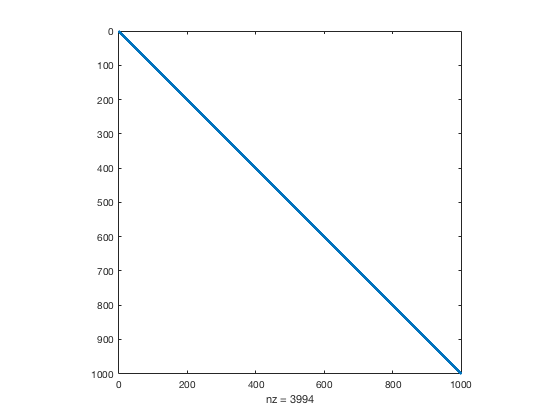

T = gallery('toeppen',1000);
spy(T)

b = T*ones(1000,1);
[sol, niter] = Jacobi(T,b)

Error using Jacobi (line 23)
La matrice A ha elementi nulli sulla diagonale. Riordinare la matrice e rieseguire l'algoritmo.

### Test di accuratezza

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z);

b = Z*e;
c = condest(Z)

c =      2.269252419481775e+00


[sol, niter, res] = Jacobi(Z, b)

Raggio spettrale:
     3.306146307515894e-01



sol =      1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00


niter =     11


res =      6.623950529603319e-08


err = norm(e-sol)/norm(sol)

err =      2.969125980155711e-08


Aumentiamo il numero di cifre significative richieste:

[sol, niter, res] = Jacobi(Z, b, 10^-13)

Raggio spettrale:
     3.306146307515894e-01



sol =      9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01


niter =     24


res =      1.234100541057016e-14


err = norm(e-sol)/norm(sol)

err =      9.608773431926683e-15


### Velocità di convergenza

Nei paragrafi precedenti è stato già notato come, all'aumentare del condizionamento e del raggio spettrale, la function converga in un numero di iterazioni maggiore. Mostriamo qui alcuni esempi.

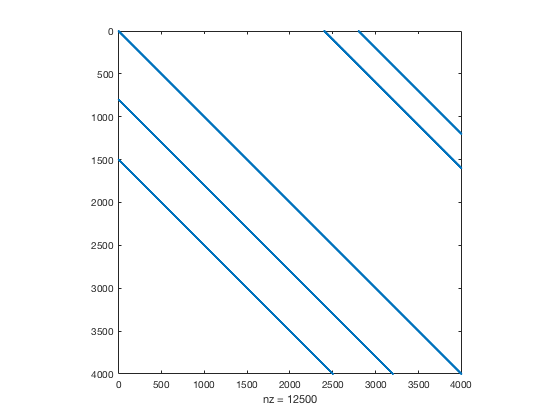

e = ones(4000,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2400 2800], 4000, 4000);
spy(Z)

b = Z*e;
c = condest(Z)

c =      4.891972054631863e+00


[sol, niter] = Jacobi(Z, b, 10^-7)

Raggio spettrale:
     5.644619182878499e-01



sol =      1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00
     1.000000004034755e+00


niter =     27


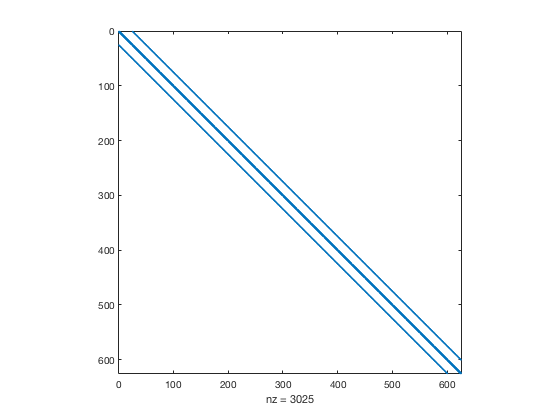

A = gallery('poisson',25);
spy(A);

c = condest(A)

c =      3.979511906492402e+02


x = ones(625,1);
b = A*x;
[sol, niter] = Jacobi(A, b, 10^-7,1800)

Raggio spettrale:
     9.927088740980539e-01



sol =      9.999998039306583e-01
     9.999996107308720e-01
     9.999994231868126e-01
     9.999992440846508e-01
     9.999990759652524e-01
     9.999989213694822e-01
     9.999987824452332e-01
     9.999986613403985e-01
     9.999985596850713e-01
     9.999984791093450e-01


niter =         1597


La prima esecuzione converge in 27 iterazioni con precisione a 7 cifre. La seconda esecuzione, a parità di cifre significative richieste, converge in 1597 iterazioni. Ciò trova una spiegazione teorica nell'aumento del raggio spettrale della matrice B calcolata dal metodo di Jacobi.

### Casi di warning

Potrebbe capitare che il numero di iterazioni massimo non sia sufficiente per ottenere il numero di cifre significative desiderato. Mostriamo di seguito alcuni esempi:

X = gallery('poisson',45);
c = condest(X)

c =      1.246644559470456e+03


x = ones(2025,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,1000)

Raggio spettrale:
     9.976687691905481e-01



sol =      9.992704954445497e-01
     9.985443905025414e-01
     9.978250847020679e-01
     9.971159140342090e-01
     9.964202142497190e-01
     9.957411952434478e-01
     9.950820665594760e-01
     9.944458519749194e-01
     9.938355748715626e-01
     9.932540164953604e-01


niter =         1000


[sol, niter] = Jacobi(X,b,10^-6,4000)

Raggio spettrale:
     9.976687691905481e-01



sol =      9.999980070151633e-01
     9.999960233333731e-01
     9.999940581710265e-01
     9.999921207445213e-01
     9.999902200119213e-01
     9.999883649312908e-01
     9.999865640354895e-01
     9.999848258573762e-01
     9.999831583456547e-01
     9.999815694490282e-01


niter =         3529


err = norm(x-sol)/norm(sol)

err =      2.187704316834668e-04


In questo caso, dato che il primo numero massimo di iterazioni è stato impostato a 1000, la function stampa un messaggio di warning specificando che il risultato potrebbe non soddisfare l'accuratezza richiesta. Se si aumenta tale parametro, la function converge al risultato con accuratezza corretta.

Il prossimo esempio, invece, mostra una matrice malcondizionata e la matrice B calcolata dal metodo ha raggio spettrale uguale a 1. In questo caso, il metodo iterativo di Jacobi non converge.

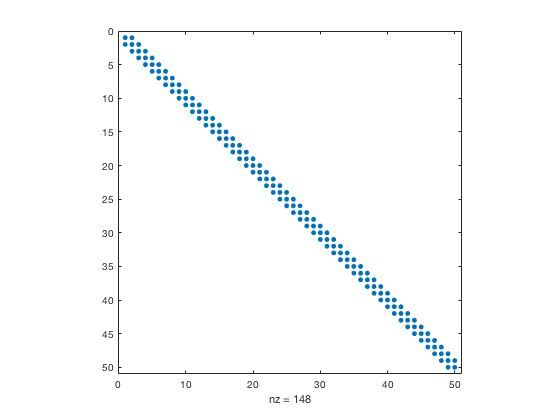

D = gallery('dorr',50);
spy(D)

c = condest(D)

c =      3.353970942409131e+06


e = ones(50,1);
b = D*e;
[sol, niter] = Jacobi(D,b,10^-6,30000)

Raggio spettrale:
     9.999969672077741e-01



sol =      5.689494803980587e-01
     3.469830582782696e-01
     2.303763712526022e-01
     1.678580040753758e-01
     1.336353733272751e-01
     1.145009919216790e-01
     1.035694781679772e-01
     9.718581267956170e-02
     9.337407307334124e-02
     9.104626916807979e-02


niter =        30000


err = norm(e-sol)/norm(sol)

err =      5.206942233857522e+00


caso in cui diagonale non strettamente dominante e buon condizionamento

% (vale per tutti i tol)

% NON CONVERGE anche con Tol = 10^-15 e aumentando le iterazioni.

W = spdiags([e 5*e 2*e -e e], [-1300 -500 0 400 2500], n, n);
spy(W);
b = W*e;
[sol4, niter4] = Jacobi(W,b,10^(-15))